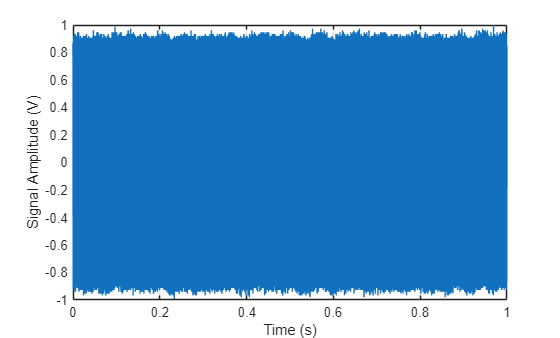

%Load the calibration data file
 load calibration.dat
% Assign the variables to data i.e(Microphone signal and Sample start time)
V = calibration(1,:); %electronic signal(Volts)
t_s = calibration(2,:);%time in seconds
V_s = V;
% Normalize the voltage signal
V_s = V_s / max(abs(V_s));
%plot of the time domain of the calibration signal
plot(t_s, V_s )
xlabel('Time (s)')
ylabel('Signal Amplitude (V)')
grid on

%converting the calibration signal from the time domain to the frequency
%domain
f_s = 1/ mean(diff(t_s)); %  sampling frequency(samples/sec)
x = detrend(V_s(:), 0);  %removes the DC offset
N = numel(x);
w = hann(N,'periodic');   % window : fade in from zero and fade out to zero which further helps to remove sampling noise and get the correct peak values
cg = mean(w);   %fixes amplitude drop cuased by window 
%take the FFT
X = fft(x .* w);
f = (0:N-1)*(f_s/N);  
N2 = floor(N/2)+1;   %finds the index of the half way point 
f = f(1:N2)';
Vmag = abs(X(1:N2))*2/(cg*N);  %calc the true amplitudes of  the spectrum
[~, pk] = max(Vmag);   
f0 = f(pk);   %calibrator frequency
V_peak = V_s(pk);
 semilogx(f, Vmag); %plot of the  calibration signal spectrum
xlabel("frequency(Hz)")
ylabel("Node Amplitude[V]")
title(sprintf('Calibration FFT, peak at %.1f Hz', f0));
p_ref = 20e-6;       % reference pressure [Pa]
%At    1kHz The calibration source generates pure tone at a 94dB therefore 
SPL_dB = 94; 
p_calib = 10^(SPL_dB/20) * p_ref;  % Calculate the calibration sound  pressure 
V_rms = rms(V_s );% root mean square of the Voltage signal values
S = V_rms/p_calib; %Microphone sensitivity
fprintf("the Microphone sensitvity of the miscrophone used is %d. VPa^-1\n",S)

the Microphone sensitvity of the miscrophone used is 6.407511e-01. VPa^-1



fprintf(' Fundamental frequency (Pure tone) ≈ %.2f Hz\n', f0);

 Fundamental frequency (Pure tone) ≈ 1000.00 Hz


fprintf(' Volatage Amplitude at Fundamental frequency  %.3f V\n', V_peak);

 Volatage Amplitude at Fundamental frequency  0.869 V


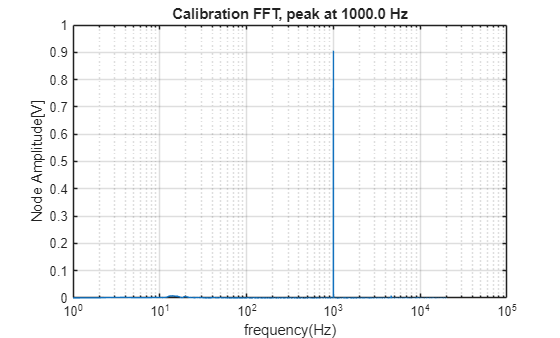

grid on

fprintf('the number of elements inside V_s %d.\n' , numel(V_s));

the number of elements inside V_s 40000.
